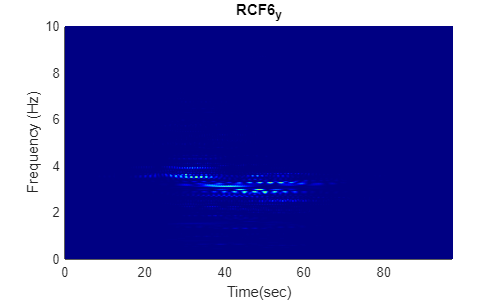

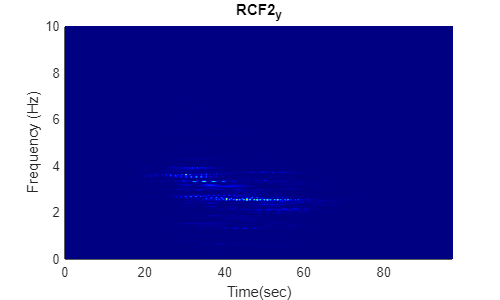

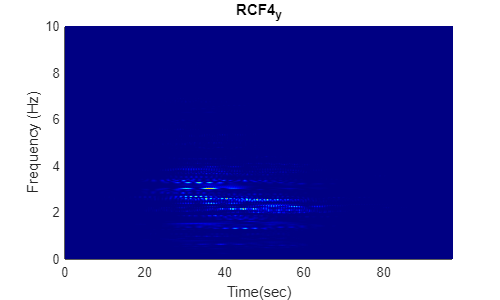

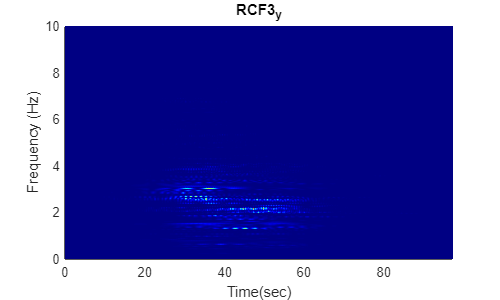

clc;clear;close all;
[data,txt,raw] = xlsread('Homework-2 data set-RCF-Four Specimen Test Data.xlsx');
t = data(:,1);
RCF6_x = data(:,2);
RCF6_y = data(:,3);
RCF2_x = data(:,4);
RCF2_y = data(:,5);
RCF4_x = data(:,6);
RCF4_y = data(:,7);
RCF3_x = data(:,8);
RCF3_y = data(:,9);
sr = round(1/(t(2)-t(1))); % sampling rate
pt = length(t);
str = [RCF6_y RCF2_y RCF4_y RCF3_y];
strname = ['RCF6_y'; 'RCF2_y'; 'RCF4_y'; 'RCF3_y'];
for i = 1:4
    [t,F,E,A,T,C] = wptspect(str(:,i),sr,11);
    temp = find(F<=50);
    figure('Position',[200 50 500 300])
    surf(t,F(temp),E(:,temp)','LineStyle','none','FaceColor','interp','FaceLighting','phong','EdgeColor','interp')
    view(0,90)
    colormap('jet')
    ylim([0 10])
    title(strname(i,:));
    xlabel('Time(sec)')
    ylabel('Frequency (Hz)')
    xlim([0 t(end)])
end


function[t,F,E,A,T,C] = wptspect(u,SR,level)
if size(u,1) == 1
    u = u';
end
wname = 'bior6.8';
dt = 1/SR;
N = max(size(u));
t = [0:dt:(N-1)*dt];
% index of paley transform
index = 0;
for i = 1:1:level
    index = [index fliplr(index)+2^(i-1)];
end
index = index + 1;
T = wpdec(u,level,wname);
for i = 1:2^level
    C(:,i) = wprcoef(T,[level,index(i)-1]);
    A(:,i) = abs(hilbert(wprcoef(T,[level,index(i)-1])));
end
E = A.*A;
F = linspace(0,1/dt/2,2^level);
end